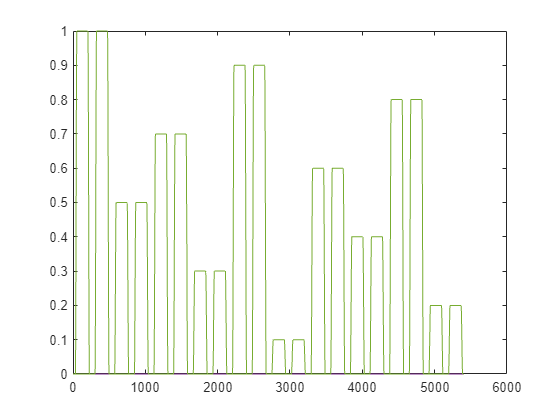

[kinematics, features, targets, kalman, nip_time] = readKDF("D:\FRM\meta-mutual-learning\data\v2-p-00-2\machine-learning\TrainingData_20230201-154233_154725.kdf");
plot(kinematics')

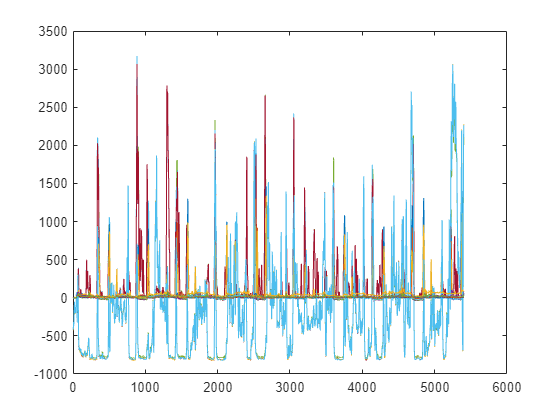

plot(features(193:225,:)')

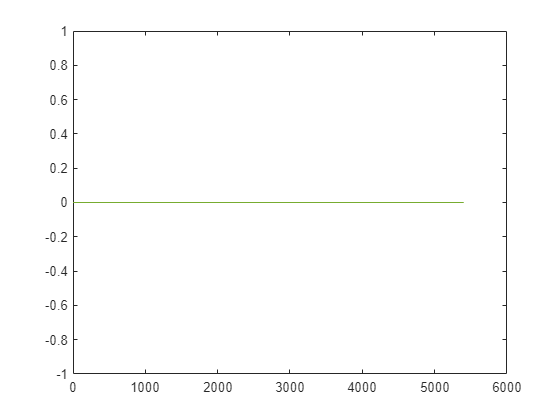

plot(kalman')

[kinematics_al, features_al] = align_training_data(kinematics, features, [], 'standard');
KF = train_decoder(kinematics, features, 193:225, 'standard');
KF_output = run_decoder(KF, kinematics_al, features_al, 193:225, 'standard');

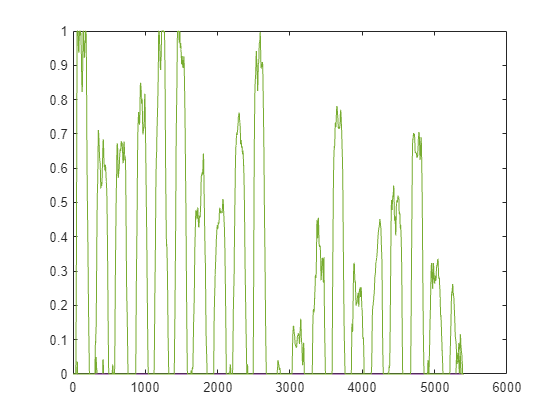

plot(KF_output')

[rmse_int, rmse_xint, ~]= compute_rmse(kinematics_al, KF_output);

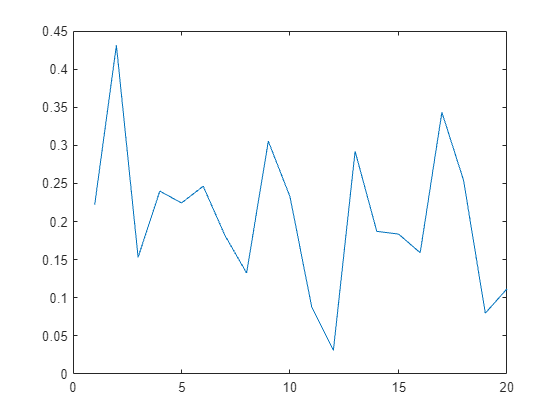

plot(rmse_int)

events = readlines("D:\FRM\meta-mutual-learning\data\v2-p-00-2\machine-learning\TrainingData_20230201-154233_154725.kef");

events = 21×1 string array
    "SS.TargOnTS=7734090;SS.TrialTS=7942950;SS.MvntMat=[1.00,0.00,0.70,5.00,;1.00,0.00,0.70,5.00,;1.00,0.00,0.70,5.00,;1.00,0.00,0.70,5.00,;1.00,0.00,0.70,5.00,;0.00,0.00,0.00,0.00,;0.00,0.00,0.00,0.00,;0.00,0.00,0.00,0.00,;0.00,0.00,0.00,0.00,;0.00,0.00,0.00,0.00,;0.00,0.00,0.00,0.00,;0.00,0.00,0.00,0.00,;];"
    "SS.TargOnTS=8003370;SS.TrialTS=8211240;SS.MvntMat=[0.00,0.00,0.00,0.00,;0.00,0.00,0.00,0.00,;0.00,0.00,0.00,0.00,;0.00,0.00,0.00,0.00,;0.00,0.00,0.00,0.00,;0.00,0.00,0.00,0.00,;0.00,0.00,0.00,0.00,;0.00,0.00,0.00,0.00,;0.00,0.00,0.00,0.00,;0.00,0.00,0.00,0.00,;0.00,0.00,0.00,0.00,;1.00,0.00,0.70,5.00,;];"
    "SS.TargOnTS=8272650;SS.TrialTS=8480520;SS.MvntMat=[0.50,0.00,0.70,5.00,;0.50,0.00,0.70,5.00,;0.50,0.00,0.70,5.00,;0.50,0.00,0.70,5.00,;0.50,0.00,0.70,5.00,;0.00,0.00,0.00,0.00,;0.00,0.00,0.00,0.00,;0.00,0.00,0.00,0.00,;0.00,0.00,0.00,0.00,;0.00,0.00,0.00,0.00,;0.00,0.00,0.00,0.00,;0.00,0.00,0.00,0.00,;];"
    "SS.TargOnTS=8540940;SS.TrialTS=8

for i=2:2:length(events)-1
    max(sscanf(events(i), "SS.TargOnTS=%d;SS.TrialTS=%d"))
end

ans = 8211240

ans = 8748810

ans = 9286380

ans = 9823950

ans = 10361460

ans = 10900050

ans = 11436540

ans = 11975160

ans = 12512700

ans = 13050300